g = 9.81;
m = 0.03;
R = 0.04

R = 0.0400

Jw = m*R^2/2;
M = 0.6;
W = 0.14;
D = 0.04;
H = 0.144;
L = H/2;
Jpsi = M*L^2/3;
Jphi = M*(W^2+D^2)/12;
Jm = 1e-5;
Rm = 6.69;
Kb = 0.468;
Kt = 0.317;
n = 1;
fm = 0.0022;
fm = ureal('fm', 0.0022,'Range',[0.001,0.005])

fm =   Uncertain real parameter "fm" with nominal value 0.0022 and range [0.001,0.005].


fw = 0.0001;
fw = ureal('fw', 0.0001,'Range',[0.00005,0.0002])

fw =   Uncertain real parameter "fw" with nominal value 0.0001 and range [5e-05,0.0002].


a = n*Kt/Rm;
b = n*Kt*Kb/Rm + fm;
s = b+fw;

e11 = (2*m+M)*R^2+2*Jw+2*Jm;
e12 = M*L*R-2*Jm;
e22 = M*L^2 + Jpsi + 2*Jm;

detE = e11*e22-e12^2;

a32 = -g*M*L*e12/detE;
a42 = g*M*L*e11/detE;
a33 = -2*(s*e22+b*e12)/detE;
a43 = 2*(s*e12+b*e11)/detE;
a34 = 2*b*(e22+e12)/detE;
a44 = -2*b*(e11+e12)/detE;
b3 = a*(e22 + e12)/detE;
b4 = -a*(e11+e12)/detE;

A = [0 0 1 0; 0 0 0 1; 0 a32 a33 a34;...
    0 a42 a43 a44];
B = [0 0; 0 0; b3 b3; b4 b4];

M = ss(A,B,eye(4),0)

M =

  Uncertain continuous-time state-space model with 4 outputs, 2 inputs, 4 states.
  The model uncertainty consists of the following blocks:
    fm: Uncertain real, nominal = 0.0022, range = [0.001,0.005], 1 occurrences
    fw: Uncertain real, nominal = 0.0001, range = [5e-05,0.0002], 1 occurrences

Type "M.NominalValue" to see the nominal value, "get(M)" to see all properties, and "M.Uncertainty" to interact with the uncertain elements.



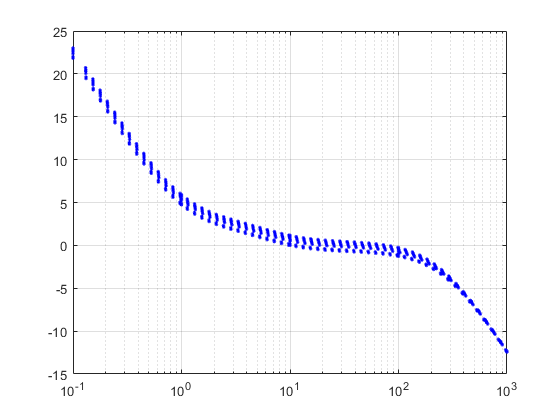

    figure;
for n=1:10
    [sig,w] = sigma(usample(M));

    semilogx(w,20*log10(sig(1,:)),'b.')
    hold on
    grid on
end


[G , D] = lftdata(M)

G =
 
  A = 
           x1      x2      x3      x4
   x1       0       0       1       0
   x2       0       0       0       1
   x3       0  -409.7  -162.6   162.1
   x4       0   269.6   78.34  -78.15
 
  B = 
            u1       u2       u3       u4
   x1        0        0        0        0
   x2        0        0        0        0
   x3   -3.773  -0.5395    157.6    157.6
   x4    1.819   0.2211   -75.96   -75.96
 
  C = 
           x1      x2      x3      x4
   y1       0       0   2.962  -2.962
   y2       0       0   0.583       0
   y3       1       0       0       0
   y4       0       1       0       0
   y5       0       0       1       0
   y6       0       0       0       1
 
  D = 
           u1      u2      u3      u4
   y1     0.4       0       0       0
   y2       0  0.3333       0       0
   y3       0       0       0       0
   y4       0       0       0       0
   y5       0       0       0       0
   y6       0       0       0       0
 
Continuous-time state-spac



s=tf('s');
Wp=[(0.57*s+0.95)/(2*s+0.024) 0 0 0 0;...
     0 0.9 0 0 0;...
     0 0 0.15 0 0;
     0 0 0 (0.242*s+0.22)/(s+1) 0;...
     0 0 0 0 (1.08*s+1.8)/(4*s+0.048)];
Wu=(0.06*s+0.04)/(0.0024*s+1)*eye(2);
Wn=[0.5*s+1 0;0 s+2]/(0.001*s+1);
int1=1/s;
G=M;
systemnames  = 'G Wp Wn Wu int1';
inputvar     = '[r{4}; n{2}; u{2}]';
outputvar    = '[Wp; Wu; r ;G(1:2);G(3:4)+Wn;int1 ]';
input_to_G   = '[u]';
input_to_int1 ='[r(1)-G(1)]';
input_to_Wp  = '[r-G; int1]';
input_to_Wu  = '[u]';
input_to_Wn =  '[n]';

P = minreal(sysic);

1 state removed.



ny=9;nu=2;
[Kinf,Ninf,gopt] = hinfsyn(P,ny,nu,'DISPLAY','on');


  Test bounds:  0.9 <=  gamma  <=  1.11

   gamma        X>=0        Y>=0       rho(XY)<1    p/f
  9.98e-01     0.0e+00     0.0e+00     3.090e-10     p
  9.48e-01     0.0e+00     0.0e+00     3.750e-10     p
  9.24e-01     0.0e+00     0.0e+00     4.257e-10     p
  9.12e-01     0.0e+00     0.0e+00     4.736e-10     p
  9.06e-01     5.6e-20     0.0e+00     5.397e-10     p

  Best performance (actual): 0.902


K = minreal(ss(Kinf));

2 states removed.


Ovo je proba

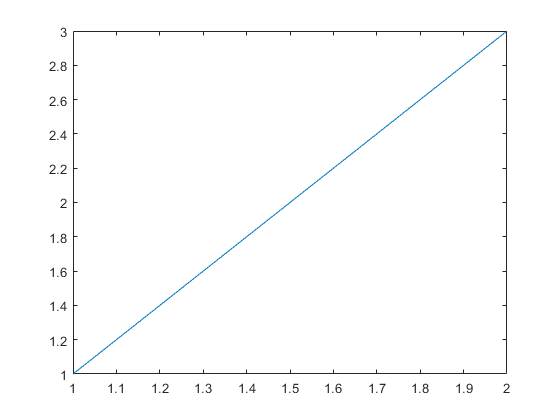

figure
plot([1 2],[1 3])

dsd

sd=332

Sranje